clear; clc;

% set(groot, 'defaultTextInterpreter', 'remove');
% set(groot, 'defaultAxesTickLabelInterpreter', 'remove');
% set(groot, 'defaultLegendInterpreter', 'remove');

Modulações a serem avaliadas, por ordem crescente de maximização espectral:

- BPSK

- QPSK

- 8-PSK

- 16-QAM

- 64-QAM

O critério de seleção da modulação a ser utilizada é a maximização da eficiência espectral para um desempenho de probabilidade de erro limitante Pe ou Pb, o qual deve ser um parâmetro de entrada da rotina. Como a eficiência cresce com k (número de bits por símbolo), será escolhida sempre a modulação de maior k que atinge o requisito de erro limitante.

É interessante que a rotina tenha, então, as seguintes entradas:

- targetMetric {'sym' ou 'bit'}

- targetErr, o Pe ou Pb alvo

- inputEbN0, em decibéis

E retorne

- o vetor com os erros (*SER *ou* BER*) das modulações escolhidas para cada EbN0, **bestErr**

- o vetor com os índices das modulações escolhidas, **bestModIdx**

function [bestErr, bestModIdx, allErr] = simulateModem(inputEbN0dB, targetErr, ...
    targetMetric, nSym)

% inicialmente definindo as modulações
mods = struct(...
    'name', {"BPSK","QPSK","8-PSK","16-QAM","64-QAM"}, ...
    'type', {'psk','psk','psk','qam','qam'}, ...
    'm', {2, 4, 8, 16, 64}, ...
    'k', {1, 2, 3, 4, 6}, ...
    'mod', {[],[],[],[],[]}, ...
    'demod', {[],[],[],[],[]} ...
);

% escolhendo as funções 'mod' e 'demod' pra cada modulação
for i = 1:numel(mods)
    if mods(i).type == "psk"
        mods(i).mod = @(x) pskmod(x, mods(i).m, 0, 'gray');
        mods(i).demod = @(y) pskdemod(y, mods(i).m, 0, 'gray');
    else
        mods(i).mod = @(x) qammod(x, mods(i).m, 'gray', 'UnitAveragePower',true);
        mods(i).demod = @(y) qamdemod(y, mods(i).m, 'gray', 'UnitAveragePower',true);
    end
end

useBER = strcmpi(targetMetric,'bit'); % será usado BER ou não?

nEbN0 = numel(inputEbN0dB); % nº de EbN0 a serem testados
nMods = numel(mods); % nº de modulações (por padrão: 5)

allErr = zeros(nMods, nEbN0);
bestErr = zeros(nEbN0,1);
bestModIdx = zeros(nEbN0,1);

bits0 = randi([0 1], nSym*6, 1, 'int8'); % bits pré-gerados
    
%% Loop principal
for idxEb = 1:nEbN0 
    EbN0 = inputEbN0dB(idxEb);       % ainda em dB
    for iMod = 1:5 % 5 modulações
        k = mods(iMod).k; % bits por símbolo da vez

        % converte em símbolos apenas a quantidade necessária de bits
        bits = bits0(1:nSym*k);
        sym = bi2de(reshape(bits,k,[]).', 'left-msb');
        tx = mods(iMod).mod(sym);

        % Converte Eb/N0 → Es/N0
        snrSym_dB = EbN0 + 10*log10(k);
        rx = awgn(tx, snrSym_dB, 'measured');

        symHat = mods(iMod).demod(rx);

        if useBER
            bitsRx = reshape(de2bi(symHat,k, 'left-msb').', [], 1);
            allErr(iMod,idxEb) = mean(bitsRx ~= bits);
        else
            allErr(iMod,idxEb) = mean(symHat ~= sym);
        end
    end

    %% Seleciona modulações que atendem ao alvo
    ok = allErr(:,idxEb) <= targetErr; % vetor booleano

    if any(ok)
        % acha o maior k dentre as válidas
        [bestK,~] = max([mods(ok).k]);
        bestModIdx(idxEb) = find([mods.k] == bestK,1);   % índice no struct
    else
        bestModIdx(idxEb) = 1;              % usa BPSK (mais robusta) mesmo
    end
    bestErr(idxEb) = allErr(bestModIdx(idxEb),idxEb);
end

end

Exercício 3: Apresente o gráfico de SER×Eb/N0 para os seguintes desempenhos de probabilidade de erro de símbolo limitante Pe = 10−2, Pe = 10−3 e Pe = 10−4.

Definições iniciais:

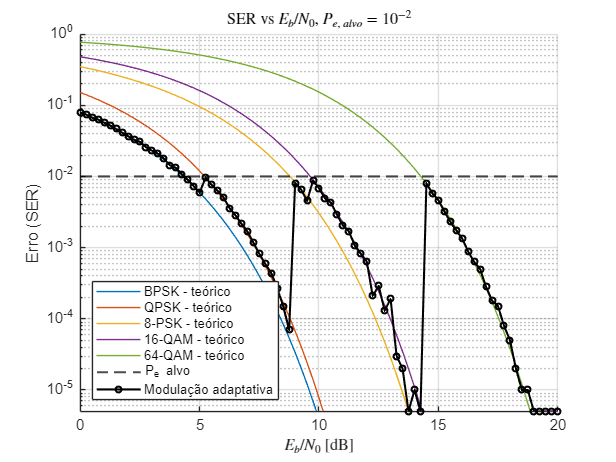

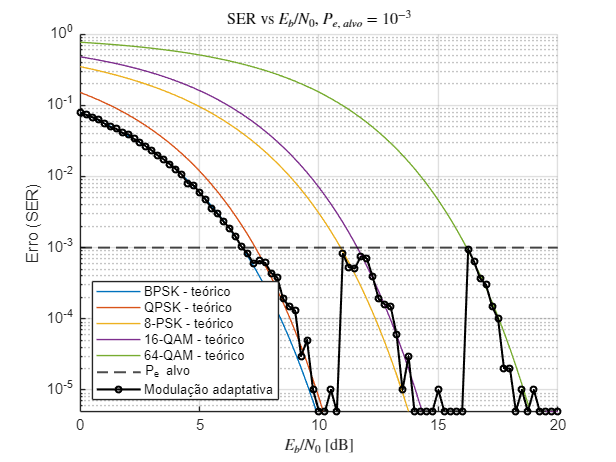

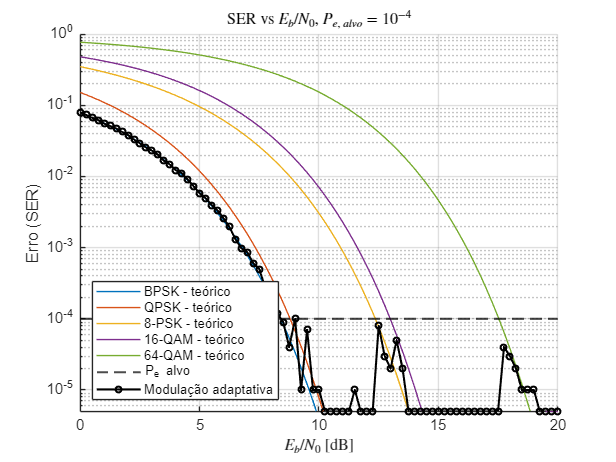

function question3(targetPe)
% Número de símbolos testados por amostra
Ns = 1e5;

% ranges de simulação
EbN0dB = 0:0.25:20;

[errBest, ~, errMatrix] = simulateModem(EbN0dB, targetPe, 'sym', Ns);

modsNames = ["BPSK","QPSK","8-PSK","16-QAM","64-QAM"];

% matriz com valores teóricos de SER
EbN0lin = 10.^(EbN0dB/10);
theo = zeros(numel(modsNames), numel(EbN0dB));

% BPSK
theo(1,:) = qfunc(sqrt(2*EbN0lin));
% QPSK (Gray)
q = qfunc(sqrt(2*EbN0lin));
theo(2,:) = 2*q - q.^2;
% 8‑PSK
theo(3,:) = 2*qfunc(sqrt(2*3*EbN0lin).*sin(pi/8));

% 16‑QAM
M = 16;
ser = 2*(1-1/sqrt(M)).*qfunc(sqrt(3*log2(M)*EbN0lin/(M-1)));
theo(4,:) = 1 - (1-ser).^2;   % eixo I+Q
% 64‑QAM
M = 64;
ser = 2*(1-1/sqrt(M)).*qfunc(sqrt(3*log2(M)*EbN0lin/(M-1)));
theo(5,:) = 1 - (1-ser).^2;

%% Substitui zeros por limite inferior para evitar -Inf no log quando 0 erros ocorrem
minErr = 0.5/Ns;                          % um erro equivalente a meio símbolo < limite inferior da simulação = 1 símbolo
errMatrix(errMatrix==0) = minErr;
theo(theo==0)           = minErr;
errBest(errBest==0)       = minErr;

figure; hold on; grid on;
% hSim = semilogy(EbN0dB, errMatrix.', 'LineWidth', 1.2);
hTheo = semilogy(EbN0dB, theo.');
hLine = yline(targetPe, 'k--', 'LineWidth',1.4);
hBest = semilogy(EbN0dB, errBest, 'k-o', 'LineWidth', 1.4, 'MarkerSize', 4);

set(gca,'YScale','log'); % força escala logarítmica

xlabel('$E_b/N_0$ [dB]', 'Interpreter', 'latex');
ylabel('Erro (SER)');
aaa = log10(targetPe);
title(sprintf('SER vs $E_b/N_0$, $P_{e,~alvo} = 10^{%g}$', aaa), 'Interpreter', 'latex');

lgd = [hTheo(:); hLine; hBest];
lgdNames = [modsNames + " - teórico", "P_e alvo", "Modulação adaptativa"];
legend(lgd, lgdNames, 'Location','southwest');
%legend(modsNames, 'Location','southwest');

axis([min(EbN0dB) max(EbN0dB) 0.5/Ns 1]);
set(gca,'YGrid','on','XGrid','on');
end

testedErrorProbabilities = [1e-2, 1e-3, 1e-4];

for Pe = testedErrorProbabilities
    question3(Pe)
end

Exercício 4: Apresente o gráfico de BER×Eb/N0 para os seguintes desempenhos de probabilidade de erro de símbolo limitante Pb = 10−2, Pb = 10−3 e Pb = 10−4.

Definições iniciais

function question4(targetPe)
% Número de símbolos testados por amostra
Ns = 5e6;

% ranges de simulação
EbN0dB = 0:0.25:20;

[errBest, ~, errMatrix] = simulateModem(EbN0dB, targetPe, 'bit', Ns);

modsNames = ["BPSK/QPSK","8-PSK","16-QAM","64-QAM"];

% matriz com valores teóricos de SER
EbN0lin = 10.^(EbN0dB/10);
theo = zeros(numel(modsNames), numel(EbN0dB));

% BPSK
theo(1,:) = qfunc(sqrt(2*EbN0lin));
% QPSK (Gray)
theo(2,:) = qfunc(sqrt(2*EbN0lin));
% 8‑PSK
theo(3,:) = 2*qfunc(sqrt(2*3*EbN0lin).*sin(pi/8))/3; % BER ~ SER/k

% 16‑QAM
M = 16; k = log2(M);
theo(4,:) = (4/k)*(1-1/sqrt(M)).* qfunc( sqrt( 3*k*EbN0lin./(M-1) ) );

% 64‑QAM
M = 64; k = log2(M);
theo(5,:) = (4/k)*(1-1/sqrt(M)).* qfunc( sqrt( 3*k*EbN0lin./(M-1) ) );

%% Substitui zeros por limite inferior para evitar -Inf no log quando 0 erros ocorrem
minErr = 0.5/Ns;                          % um erro equivalente a meio símbolo < limite inferior da simulação = 1 símbolo
errMatrix(errMatrix==0) = minErr;
theo(theo==0)           = minErr;
errBest(errBest==0)       = minErr;

figure; hold on; grid on;
% hSim = semilogy(EbN0dB, errMatrix.', 'LineWidth', 1.2);
hTheo = semilogy(EbN0dB, theo(2:5,:).');
hLine = yline(targetPe, 'k--', 'LineWidth',1.4);
hBest = semilogy(EbN0dB, errBest, 'k-o', 'LineWidth', 1.4, 'MarkerSize', 4);

set(gca,'YScale','log'); % força escala logarítmica

xlabel('$E_b/N_0$ [dB]', 'Interpreter', 'latex');
ylabel('Erro (BER)');
aaa = log10(targetPe);
title(sprintf('BER vs $E_b/N_0$, $P_{b,~alvo} = 10^{%g}$', aaa), 'Interpreter', 'latex');

lgd = [hTheo(:); hLine; hBest];
lgdNames = [modsNames + " - teórico", "P_b alvo", "Modulação adaptativa"];
legend(lgd, lgdNames, 'Location','northeast');
%legend(modsNames, 'Location','southwest');

axis([min(EbN0dB) max(EbN0dB) 0.5/Ns 1]);
set(gca,'YGrid','on','XGrid','on');
end

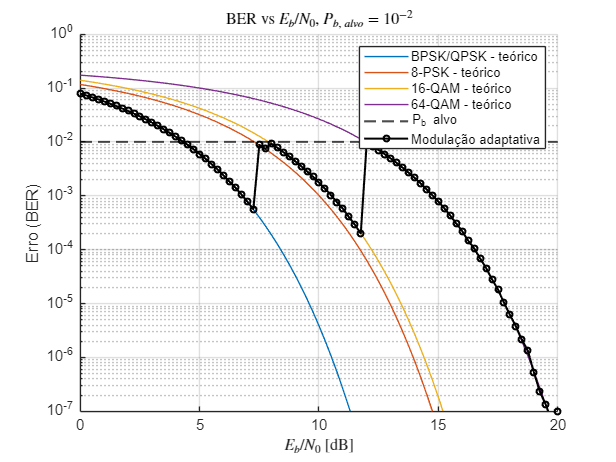

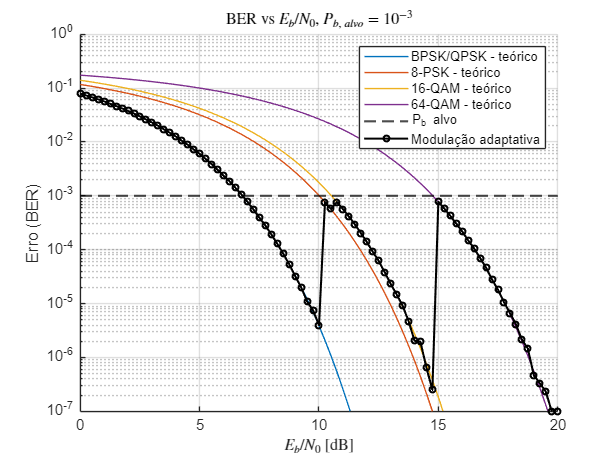

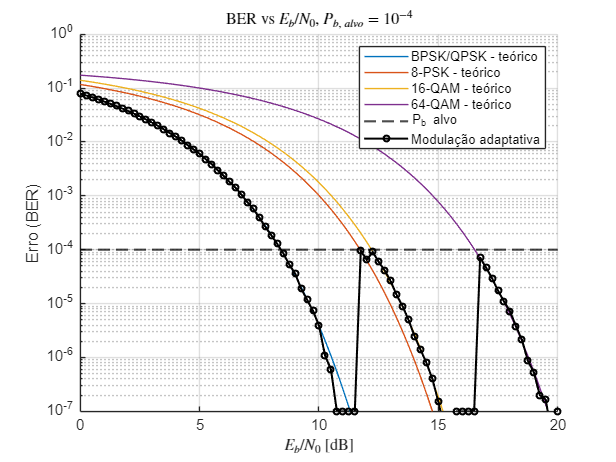

testedErrorProbabilities = [1e-2, 1e-3, 1e-4];


for Pe = testedErrorProbabilities
    question4(Pe)
end

Questão 5: modulações por faixa de Eb/N0:

Olhando pros gráficos da questão 3, caso Pe = 1e-4, e considerando que as simulações foram feitas com um passo em Eb/N0 igual a 0.25 dB, temos uma certa precisão para determinar as faixas pedidas. Considerando, ainda, que para valores pequenos de Eb/N0, onde o SER não é suficientemente pequeno, escolhe-se, ainda assim, a modulação BPSK, por ser a de menor erro teórico. Isto posto, as faixas de operação de cada modulação são:

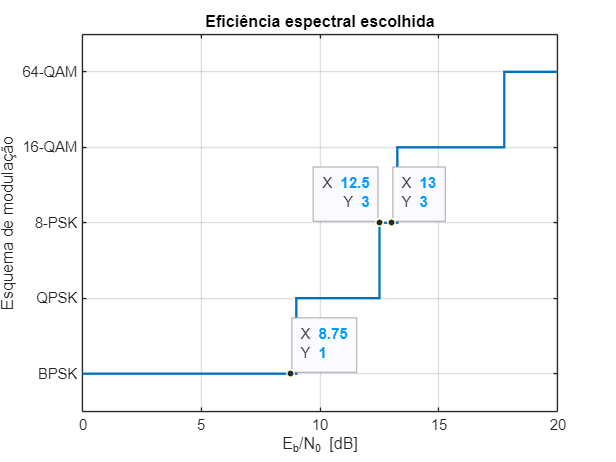

% Número de símbolos testados por amostra
Ns = 1e6;

% ranges de simulação
EbN0dB = 0:0.25:20;

[~, modIdx, ~] = simulateModem(EbN0dB, 1e-4, 'sym', Ns);

modsNames = ["BPSK","QPSK","8-PSK","16-QAM","64-QAM"];

% Plotando as faixas:
figure;
stairs(EbN0dB, modIdx, 'LineWidth',1.6);
grid on, xlabel('E_b/N_0 [dB]');
yticks(1:numel(modsNames))
yticklabels(modsNames)
ylim([0.5 5.5])

ylabel('Esquema de modulação')
title('Eficiência espectral escolhida');

Questão 6: modulações por faixa de Eb/N0:

De maneira análoga à questão 5, testam-se aqui os valores especificados em enunciado:

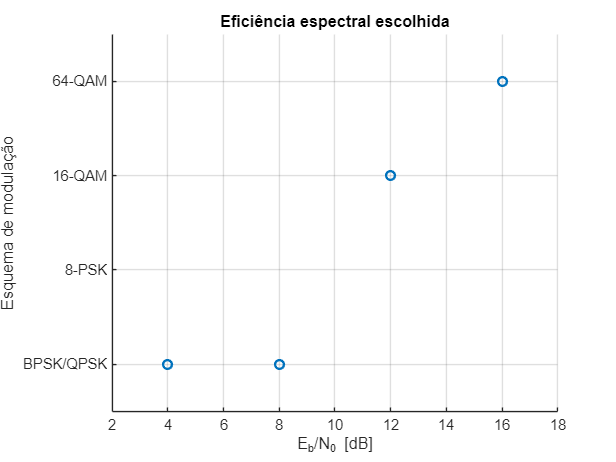

% Número de símbolos testados por amostra
Ns = 1e7;

% ranges de simulação
EbN0dB = 4:4:16;

[~, modIdx, ~] = simulateModem(EbN0dB, 1e-3, 'bit', Ns);

modsNames = ["_", "BPSK/QPSK","8-PSK","16-QAM","64-QAM"];

modIdx(modIdx==1) = 2;

% Plotando as faixas:
figure;
scatter(EbN0dB, modIdx, 'LineWidth',1.6);
grid on, xlabel('E_b/N_0 [dB]');
yticks(1:numel(modsNames))
yticklabels(modsNames)
ylim([1.5 5.5])
xlim([2 18])
ylabel('Esquema de modulação')

title('Eficiência espectral escolhida');